# The Basics

%Load the data.
load EMGdataWeek10.mat

%tells you which variables you have in your data
%who

%for data_ch1 and data_ch2, row = trail + column = time
num_trials = size(data_ch1,1);

%sampling interval
dt = times_ms(2) - times_ms(1);

# Trial 1 Data from both channels

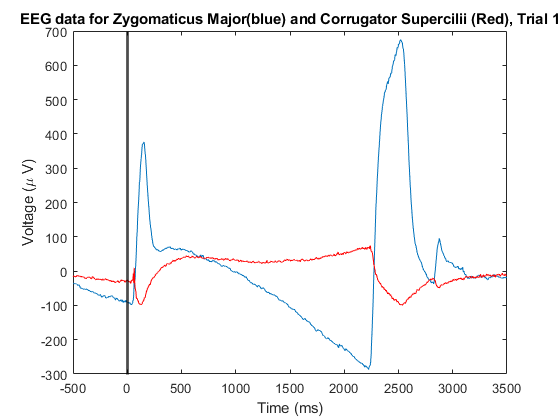

figure(1)
plot(times_ms, data_ch1(1,:)) %...data from zygomaticus major, trial 1
hold on
plot(times_ms,data_ch2(1,:), 'r') %... data from corrugator supercilii, trial 1
xlabel("Time (ms)")  %Label the x-axis as time.
ylabel("Voltage (\mu V)") %Label the y-axis as voltage.
title("EEG data for Zygomaticus Major(blue) and Corrugator Supercilii (Red), Trial 1")
xline(0, 'k', 'LineWidth', 2);
hold off %Release the current plot.

# EEG Data for ch1, All Trials

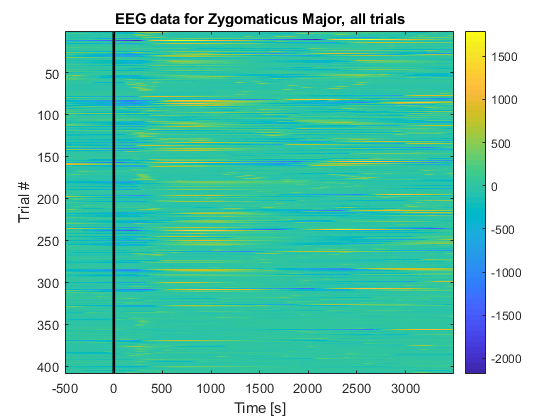

figure(2)
imagesc(times_ms,(1:num_trials),data_ch1); %Image the data from Zygomaticus Major.
colorbar;
xlabel('Time [s]') %Label the x-axis.
ylabel('Trial #') %Label the y-axis.
title("EEG data for Zygomaticus Major, all trials")
hold on %Indicate time of stimulus onset.
plot([0.25, 0.25], [0 1000], 'k', 'LineWidth', 2)
hold off

%warm colors = high voltages/ cool colors = lower voltages

# EEG Data for ch2, All Trials

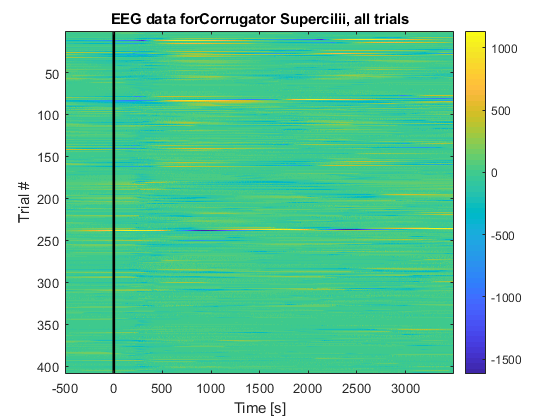

figure(3)
imagesc(times_ms,(1:num_trials),data_ch2); %Image the data from Corrugator Supercilii.
colorbar;
xlabel('Time [s]') %Label the x-axis.
ylabel('Trial #') %Label the y-axis.
title("EEG data forCorrugator Supercilii, all trials")
hold on %Indicate time of stimulus onset.
plot([0.25, 0.25], [0 1000], 'k', 'LineWidth', 2)
hold off

%warm colors = high voltages/ cool colors = lower voltages

# ERP (mean of all trials) of Ch1

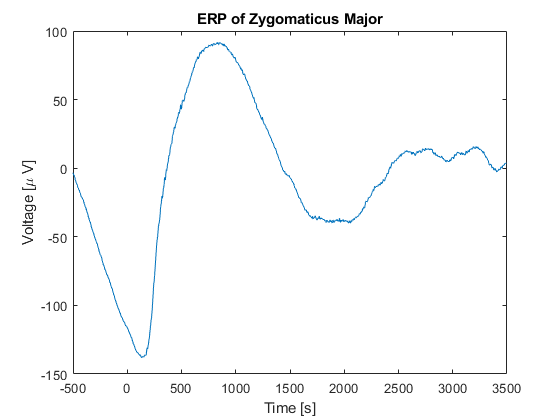

figure(4)
plot(times_ms, mean(data_ch1,1)) %Plot the ERP of Zygomaticus Major.
xlabel('Time [s]') %Label the x-axis as time,
ylabel('Voltage [\mu V]') %...and the y-axis as voltage,
title('ERP of Zygomaticus Major') %...and provide a useful title.

# ERP (mean of all trials) of Ch2

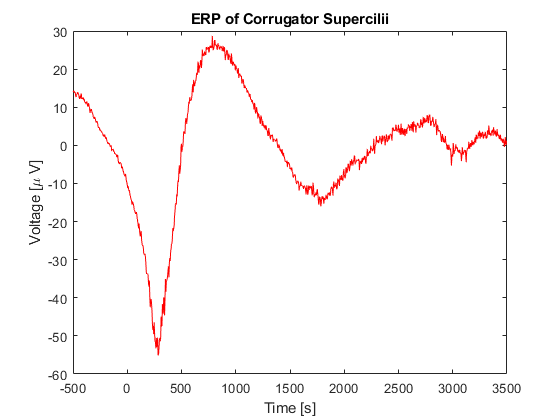

figure(5)
plot(times_ms, mean(data_ch2,1), 'r') %Plot the ERP of Corrugator Supercilii.
xlabel('Time [s]') %Label the x-axis as time,
ylabel('Voltage [\mu V]') %...and the y-axis as voltage,
title('ERP of Corrugator Supercilii') %...and provide a useful title.

# ERP of Ch1 for Smiling and Frowning

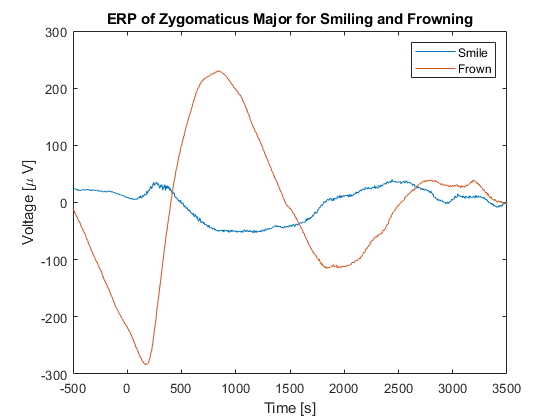

figure(6)
plot(times_ms, mean(data_ch1(labels == "S pressed",:)))
hold on
plot(times_ms, mean(data_ch1(labels == "F pressed",:)))
legend({"Smile", "Frown"})
xlabel('Time [s]') %Label the x-axis as time,
ylabel('Voltage [\mu V]') %...and the y-axis as voltage
title("ERP of Zygomaticus Major for Smiling and Frowning")
hold off

# EEG data for Ch1, all trials, smiling

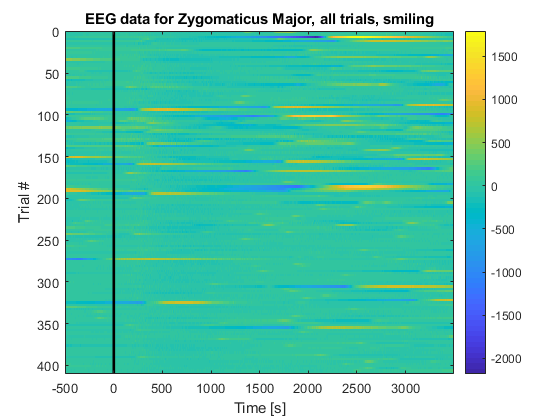

figure(7)
imagesc(times_ms,(1:num_trials),data_ch1(labels == "S pressed",:)); %Image the data from Zygomaticus Major.
colorbar;
xlabel('Time [s]') %Label the x-axis.
ylabel('Trial #') %Label the y-axis.
title("EEG data for Zygomaticus Major, all trials, smiling")
hold on %Indicate time of stimulus onset.
plot([0.25, 0.25], [0 1000], 'k', 'LineWidth', 2)
hold off

%warm colors = high voltages/ cool colors = lower voltages

# EEG data for Ch1, all trials, frowning

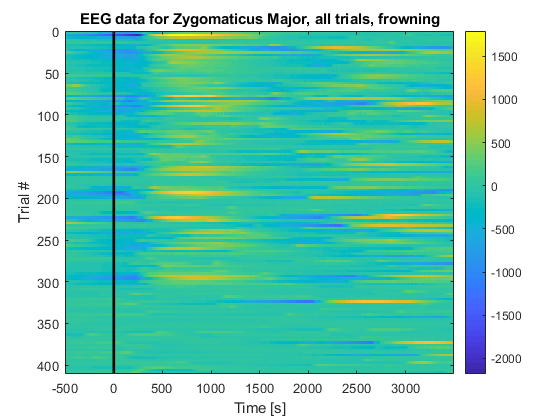

figure(8)
imagesc(times_ms,(1:num_trials),data_ch1(labels == "F pressed",:)); %Image the data from Zygomaticus Major.
colorbar;
xlabel('Time [s]') %Label the x-axis.
ylabel('Trial #') %Label the y-axis.
title("EEG data for Zygomaticus Major, all trials, frowning")
hold on %Indicate time of stimulus onset.
plot([0.25, 0.25], [0 1000], 'k', 'LineWidth', 2)
hold off

%warm colors = high voltages/ cool colors = lower voltages